clear variables;
%% parameters Setting

% Input parameters Setting
workingMode = 2;            % 1: K-mesh at xy plane;  2: K-path at high-symmetry path
fermiLevel = -2.4474445;    % Should be defined in K-path Working Mode
fittingNeighbourOrder = 19;  % Fitting Order
% initialHoppingParameter = [-2.45, ones(1, fittingNeighbourOrder)];
% initialHoppingParameter = [-2.430432, -0.040101, 0.097522, -0.070591, 0.0176250];
% initialHoppingParameter = [-2.430432, -0.040101, 0.097522, -0.070591, 0.0176250, -0.027414, 0.0046590, 0.001030, -0.010559, 0.000786];
initialHoppingParameter = [-2.430432, -0.040101, 0.097522, -0.070591, 0.0176250, -0.027414, 0.0046590, 0.001030, -0.010559, 0.000786, ...
    0.006749, -0.009858, 0.002722, -0.001447, 0.005350, -0.004718, 0.000434, 0.000423, 0.002563, 0.001689];

%% Initialize fitting function (DO NOT EDIT THIS SECTION)
% Lattice Construction
a1 = [3.3291   -0.0000    0.0000];
a2 = [-1.6645    2.8831   -0.0000];
a3 = [0.0000   -0.0000   23.1180];
% Hopping Matrix & Hopping Parameter Construction
hoppingMatrix{1} = [0, 0, 0];
hoppingMatrix{2} = [-1, 0, 0; -1, -1, 0; 0, 1, 0; 0, -1, 0; 1, 1, 0; 1, 0, 0];
hoppingMatrix{3} = [-2, -1, 0; -1, 1, 0; -1, -2, 0; 1, 2, 0; 1, -1, 0; 2, 1, 0];
hoppingMatrix{4} = [-2, 0, 0; -2, -2, 0; 0, 2, 0; 0, -2, 0; 2, 2, 0; 2, 0, 0];
hoppingMatrix{5} = [-3,-1,0;-3,-2,0;-2,1,0;-2,-3,0;-1,2,0;-1,-3,0;1,3,0;1,-2,0;2,3,0;2,-1,0;3,2,0;3,1,0];
hoppingMatrix{6} = [-3,0,0;-3,-3,0;0,3,0;0,-3,0;3,3,0;3,0,0];
hoppingMatrix{7} = [-4,-2,0;-2,2,0;-2,-4,0;2,4,0;2,-2,0;4,2,0];
hoppingMatrix{8} = [-4,-1,0;-4,-3,0;-3,1,0;-3,-4,0;-1,3,0;-1,-4,0;1,4,0;1,-3,0;3,4,0;3,-1,0;4,3,0;4,1,0];
hoppingMatrix{9} = [-4,0,0;-4,-4,0;0,4,0;0,-4,0;4,4,0;4,0,0];
hoppingMatrix{10}= [-5,-2,0;-5,-3,0;-3,2,0;-3,-5,0;-2,3,0;-2,-5,0;2,5,0;2,-3,0;3,5,0;3,-2,0;5,3,0;5,2,0];
hoppingMatrix{11}= [-5,-1,0;-5,-4,0;-4,1,0;-4,-5,0;-1,4,0;-1,-5,0;1,5,0;1,-4,0;4,5,0;4,-1,0;5,4,0;5,1,0];
hoppingMatrix{12}=[-5,0,0;-5,-5,0;0,5,0;0,-5,0;5,5,0;5,0,0];
hoppingMatrix{13}=[-6,-3,0;-3,3,0;-3,-6,0;3,6,0;3,-3,0;6,3,0];
hoppingMatrix{14}=[-6,-2,0;-6,-4,0;-4,2,0;-4,-6,0;-2,4,0;-2,-6,0;2,6,0;2,-4,0;4,6,0;4,-2,0;6,4,0;6,2,0];
hoppingMatrix{15}=[-6,-1,0;-6,-5,0;-5,1,0;-5,-6,0;-1,5,0;-1,-6,0;1,6,0;1,-5,0;5,6,0;5,-1,0;6,5,0;6,1,0];
hoppingMatrix{16}=[-6,0,0;-6,-6,0;0,6,0;0,-6,0;6,6,0;6,0,0];
hoppingMatrix{17}=[-7,-3,0;-7,-4,0;-4,3,0;-4,-7,0;-3,4,0;-3,-7,0;3,7,0;3,-4,0;4,7,0;4,-3,0;7,4,0;7,3,0];
hoppingMatrix{18}=[-7,-2,0;-7,-5,0;-5,2,0;-5,-7,0;-2,5,0;-2,-7,0;2,7,0;2,-5,0;5,7,0;5,-2,0;7,5,0;7,2,0];
hoppingMatrix{19}=[-7,-1,0;-7,-6,0;-6,1,0;-6,-7,0;-1,6,0;-1,-7,0;1,7,0;1,-6,0;6,7,0;6,-1,0;7,6,0;7,1,0];
hoppingMatrix{20}=[-8,-4,0;-4,4,0;-4,-8,0;4,8,0;4,-4,0;8,4,0];
hoppingParameter{1} = -2.430432;
hoppingParameter{2} = -0.0401010000000000;
hoppingParameter{3} = 0.0975220000000000;
hoppingParameter{4} = -0.0705910000000000;
hoppingParameter{5} = 0.0176250000000000;
hoppingParameter{6} = -0.0274140000000000;
hoppingParameter{7} = 0.00465900000000000;
hoppingParameter{8} = 0.00103000000000000;
hoppingParameter{9} = -0.0105590000000000;
hoppingParameter{10}= 0.000786000000000000;
hoppingParameter{11}= 0.00674900000000000;
hoppingParameter{12}= -0.00985800000000000;
hoppingParameter{13}= 0.00272200000000000;
hoppingParameter{14}= -0.00144700000000000;
hoppingParameter{15}= 0.00535000000000000;
hoppingParameter{16}= -0.00471800000000000;
hoppingParameter{17}= 0.000434000000000000;
hoppingParameter{18}= 0.000423000000000000;
hoppingParameter{19}= 0.00256300000000000;
hoppingParameter{20}= 0.00168900000000000;

% Lattice data Processing
transMatA = [a1;a2;a3];
V = dot(a1, cross(a2, a3));
b1 = 2*pi*cross(a2,a3)/V;
b2 = 2*pi*cross(a3,a1)/V;
b3 = 2*pi*cross(a1,a2)/V;
transMatB = [b1;b2;b3];

if workingMode == 2
% Generates K-Path (Path Working Mode)
    kpoints{1} = [0 0 0]* transMatB;
    kpoints{2} = [0 0.5 0]* transMatB;
    kpoints{3} = [-0.3333 0.6667 0.0]* transMatB;
    kpoints{4} = [0 0 0]* transMatB;
    Ntot = 51;
    for loopIndex = 1: length(kpoints) - 1
        kPointsMesh(Ntot*(loopIndex - 1) + 1: Ntot* loopIndex, 1: 3) = [linspace(kpoints{loopIndex}(1), kpoints{loopIndex + 1}(1), Ntot)', linspace(kpoints{loopIndex}(2), kpoints{loopIndex + 1}(2), Ntot)', ...
            linspace(kpoints{loopIndex}(3), kpoints{loopIndex + 1}(3), Ntot)'];
    end
    numIdx = Ntot: Ntot:(length(kpoints) - 2)*Ntot;
    kPointsMesh(numIdx, :) = [];
    kPathDistance = 0;
    kPointsMesh(1, 4) = 0;
    for loopIndex = 2: length(kPointsMesh)
        sqrtPart(1) = (kPointsMesh(loopIndex, 1) - kPointsMesh(loopIndex - 1, 1));
        sqrtPart(2) = (kPointsMesh(loopIndex, 2) - kPointsMesh(loopIndex - 1, 2));
        sqrtPart(3) = (kPointsMesh(loopIndex, 3) - kPointsMesh(loopIndex - 1, 3));
        kPathDistance = kPathDistance + sqrt(sqrtPart(1)^2 + sqrtPart(2)^2 + sqrtPart(3)^2 );
        kPointsMesh(loopIndex, 4) = kPathDistance;
    end
    kPointsMesh = kPointsMesh';
    load('wannier90_band.dat');
    % Interpolante the wannier fitting results for calculating difference.
    interpGrid = griddedInterpolant(wannier90_band(:, 1), wannier90_band(:, 2), 'linear');
    targetHkin = interpGrid(kPointsMesh(4, :)) - fermiLevel;
else
% OR import K-mesh (Plane Working Mode)
     load('savedFigureData.mat');
     selectionIndex = ~isnan(exportData.bandStructure_3D.bandeigenvalueSelected);
     kPointsMesh = exportData.hubbardModel.kpointsRecipMeshSelected(1:3, selectionIndex);
     targetHkin = exportData.hubbardModel.bandeigenvalueSelected(selectionIndex);
end

Function Fitting (Solver should be placed in this section)

Here is an illustration about setting the solver

Target Function: (x, y, F(x, y))

For workingMode = 1:  Target Function:    x             -> kPointsMesh(1, :)',

                                                                   y             -> kPointsMesh(2, :)'

                                                                   F(x, y)     -> targetHkin 

                                       Fitting Function:   x             -> kPointsMesh(1, :)',

                                                                    y            -> kPointsMesh(2, :)'

                                                                    F(x, y)     -> Hkin

For workingMode = 2:  Target Function:    x              -> kPointsMesh(4, :)',

                                                                    F(x)        -> targetHkin 

                      Fitting Function:                     x            -> kPointsMesh(4, :)',

                                                                    F(x)        -> Hkin

## Initialize solver

Solver-based Optimizer

- Create Problem, Linear Constrains, and Solution

 
 Iteration   Func-count     min f(x)         Procedure
     0            1        0.0692134         
     1           21        0.0631982         initial simplex


     2           23        0.0631982         contract outside


     3           25        0.0631982         contract inside


     4           27        0.0631982         contract inside


     5           29        0.0607943         reflect


     6           31        0.0607943         contract inside


     7           33        0.0602117         reflect


     8           35        0.0591647         reflect


     9           37        0.0582079         reflect


    10           39        0.0576776         reflect


    11           40        0.0576776         reflect


    12           41        0.0576776         reflect


    13           42        0.0576776         reflect


    14           43        0.0576776         reflect


    15           44        0.0576776         reflect


    16           45        0.0576776         reflect


    17           46        0.0576776         reflect


    18           47        0.0576776         reflect


    19           48        0.0576776         reflect


    20           49        0.0576776         reflect


    21           51        0.0576776         contract inside


    22           53        0.0576776         contract inside


    23           54        0.0576776         reflect


    24           56        0.0576776         contract inside


    25           58        0.0576776         contract inside


    26           60        0.0576776         contract inside


    27           61        0.0576776         reflect


    28           63        0.0576776         contract inside


    29           64        0.0576776         reflect


    30           66        0.0576776         contract inside


    31           67        0.0576776         reflect


    32           69        0.0576776         contract outside


    33           71        0.0576776         contract inside


    34           72        0.0576776         reflect


    35           73        0.0576776         reflect


    36           74        0.0576776         reflect


    37           75        0.0576776         reflect


    38           77        0.0576776         contract inside


    39           78        0.0576776         reflect


    40           80        0.0576776         contract inside


    41           82        0.0576776         contract inside


    42           83        0.0576776         reflect


    43           85        0.0576776         contract inside


    44           86        0.0576776         reflect


    45           87        0.0576776         reflect


    46           89        0.0576776         contract inside


    47           91        0.0576776         contract inside


    48           92        0.0576776         reflect


    49           93        0.0576776         reflect


    50           95        0.0576776         contract inside


    51           96        0.0576776         reflect


    52           98        0.0576776         contract inside


    53          100        0.0576776         contract inside


    54          101        0.0576776         reflect


    55          103        0.0576776         contract inside


    56          105        0.0576776         contract outside


    57          107        0.0576776         contract inside


    58          109        0.0576776         contract inside


    59          110        0.0576776         reflect


    60          111        0.0576776         reflect


    61          113        0.0576776         contract inside


    62          115        0.0576776         contract inside


    63          117        0.0576776         contract inside


    64          119        0.0576776         contract inside


    65          120        0.0576776         reflect


    66          122        0.0576776         contract inside


    67          124        0.0576776         contract outside


    68          126        0.0576776         contract inside


    69          127        0.0576776         reflect


    70          128        0.0576776         reflect


    71          130        0.0576776         contract inside


    72          132        0.0576776         contract inside


    73          134        0.0576776         contract inside


    74          136        0.0576776         contract inside


    75          137        0.0576776         reflect


    76          139        0.0560761         expand


    77          140        0.0560761         reflect


    78          141        0.0560761         reflect


    79          142        0.0560761         reflect


    80          144        0.0560761         contract inside


    81          145        0.0560761         reflect


    82          146        0.0560761         reflect


    83          148        0.0560761         contract inside


    84          149        0.0560761         reflect


    85          150        0.0560761         reflect


    86          151        0.0560761         reflect


    87          153        0.0560761         contract inside


    88          154        0.0560761         reflect


    89          155        0.0560761         reflect


    90          157        0.0560761         contract inside


    91          159        0.0560761         contract inside


    92          160        0.0560761         reflect


    93          161        0.0560761         reflect


    94          162        0.0560761         reflect


    95          163        0.0560761         reflect


    96          164        0.0560761         reflect


    97          165        0.0560761         reflect


    98          167        0.0560761         contract inside


    99          168        0.0560761         reflect


   100          170        0.0551619         expand


   101          171        0.0551619         reflect


   102          172        0.0551619         reflect


   103          173        0.0551619         reflect


   104          175        0.0551619         contract inside


   105          176        0.0551619         reflect


   106          178        0.0551619         contract inside


   107          179        0.0551619         reflect


   108          180        0.0551619         reflect


   109          181        0.0551619         reflect


   110          182        0.0551619         reflect


   111          184        0.0551619         contract outside


   112          185        0.0551619         reflect


   113          186        0.0551619         reflect


   114          187        0.0551619         reflect


   115          188        0.0551619         reflect


   116          189        0.0551619         reflect


   117          190        0.0551619         reflect


   118          191        0.0551619         reflect


   119          192        0.0551619         reflect


   120          193        0.0551619         reflect


   121          194        0.0551619         reflect


   122          196          0.05395         expand


   123          197          0.05395         reflect


   124          198          0.05395         reflect


   125          199          0.05395         reflect


   126          201        0.0534505         expand


   127          202        0.0534505         reflect


   128          203        0.0534505         reflect


   129          204        0.0534505         reflect


   130          205        0.0534505         reflect


   131          206        0.0534505         reflect


   132          208         0.053383         reflect


   133          210         0.053161         reflect


   134          212        0.0530989         reflect


   135          213        0.0530989         reflect


   136          215        0.0527737         reflect


   137          216        0.0527737         reflect


   138          217        0.0527737         reflect


   139          218        0.0527737         reflect


   140          219        0.0527737         reflect


   141          220        0.0527737         reflect


   142          221        0.0527737         reflect


   143          223        0.0527737         contract inside


   144          225        0.0527737         contract inside


   145          226        0.0527737         reflect


   146          227        0.0527737         reflect


   147          228        0.0527737         reflect


   148          230        0.0527737         contract inside


   149          232        0.0527737         contract inside


   150          234        0.0527737         contract inside


   151          236        0.0527737         contract inside


   152          238        0.0527737         contract inside


   153          240        0.0527572         reflect


   154          241        0.0527572         reflect


   155          243        0.0527572         contract inside


   156          245        0.0527572         contract inside


   157          247        0.0527572         contract inside


   158          249        0.0527572         contract inside


   159          251        0.0527572         contract inside


   160          253        0.0527572         contract inside


   161          255        0.0527572         contract inside


   162          256        0.0527572         reflect


   163          258        0.0527572         contract inside


   164          260        0.0527572         contract inside


   165          262        0.0527572         contract inside


   166          264        0.0527572         contract inside


   167          265        0.0527572         reflect


   168          267        0.0527572         contract inside


   169          269        0.0527572         contract inside


   170          271        0.0527572         contract inside


   171          273        0.0527572         contract inside


   172          275        0.0527552         contract inside


   173          277        0.0527444         contract inside


   174          278        0.0527444         reflect


   175          280        0.0527444         contract inside


   176          282        0.0526747         contract inside


   177          284        0.0526747         contract inside


   178          286        0.0526747         contract inside


   179          288        0.0526747         contract inside


   180          290        0.0526688         contract inside


   181          292        0.0526688         contract inside


   182          294        0.0526435         contract inside


   183          296        0.0526435         contract inside


   184          297        0.0526435         reflect


   185          299        0.0526435         contract inside


   186          301        0.0526435         contract inside


   187          303        0.0526435         contract inside


   188          305        0.0526435         contract inside


   189          307        0.0526435         contract inside


   190          309        0.0526435         contract inside


   191          311        0.0526435         contract inside


   192          312        0.0526435         reflect


   193          314        0.0526435         contract inside


   194          316        0.0525619         contract inside


   195          318        0.0525619         contract inside


   196          320         0.052494         reflect


   197          322         0.052494         contract inside


   198          323         0.052494         reflect


   199          325         0.052494         contract inside


   200          327         0.052494         contract inside


   201          328         0.052494         reflect


   202          330         0.052494         contract inside


   203          331         0.052494         reflect


   204          333         0.052494         contract inside


   205          334         0.052494         reflect


   206          336         0.052494         contract inside


   207          338         0.052494         contract inside


   208          340         0.052494         contract inside


   209          342         0.052494         contract inside


   210          344         0.052494         contract inside


   211          346         0.052494         contract inside


   212          348         0.052494         contract inside


   213          350         0.052494         contract inside


   214          352         0.052494         contract outside


   215          354         0.052494         contract inside


   216          356         0.052494         contract inside


   217          357         0.052494         reflect


   218          359         0.052494         contract inside


   219          361         0.052494         contract inside


   220          362         0.052494         reflect


   221          364         0.052494         contract inside


   222          365         0.052494         reflect


   223          367         0.052494         contract inside


   224          369         0.052494         contract inside


   225          370         0.052494         reflect


   226          372         0.052494         contract inside


   227          374         0.052494         contract inside


   228          376         0.052494         contract inside


   229          378         0.052494         contract inside


   230          380        0.0524605         contract inside


   231          381        0.0524605         reflect


   232          383        0.0524605         contract inside


   233          384        0.0524605         reflect


   234          385        0.0524605         reflect


   235          387        0.0524605         contract inside


   236          388        0.0524605         reflect


   237          390        0.0524605         contract outside


   238          391        0.0524605         reflect


   239          393        0.0524605         contract inside


   240          394        0.0524605         reflect


   241          396        0.0524605         contract inside


   242          397        0.0524605         reflect


   243          398        0.0524605         reflect


   244          399        0.0524605         reflect


   245          400        0.0524605         reflect


   246          402        0.0524184         reflect


   247          403        0.0524184         reflect


   248          404        0.0524184         reflect


   249          406        0.0524184         contract inside


   250          407        0.0524184         reflect


   251          408        0.0524184         reflect


   252          410        0.0524184         contract inside


   253          411        0.0524184         reflect


   254          412        0.0524184         reflect


   255          413        0.0524184         reflect


   256          414        0.0524184         reflect


   257          416        0.0524184         contract inside


   258          417        0.0524184         reflect


   259          418        0.0524184         reflect


   260          420        0.0523473         expand


   261          422        0.0523473         contract inside


   262          423        0.0523473         reflect


   263          424        0.0523473         reflect


   264          425        0.0523473         reflect


   265          426        0.0523473         reflect


   266          427        0.0523473         reflect


   267          428        0.0523473         reflect


   268          429        0.0523473         reflect


   269          430        0.0523473         reflect


   270          432        0.0522336         expand


   271          434        0.0522336         contract inside


   272          435        0.0522336         reflect


   273          436        0.0522336         reflect


   274          437        0.0522336         reflect


   275          438        0.0522336         reflect


   276          439        0.0522336         reflect


   277          440        0.0522336         reflect


   278          441        0.0522336         reflect


   279          442        0.0522336         reflect


   280          443        0.0522336         reflect


   281          444        0.0522336         reflect


   282          445        0.0522336         reflect


   283          446        0.0522336         reflect


   284          447        0.0522336         reflect


   285          448        0.0522336         reflect


   286          449        0.0522336         reflect


   287          451        0.0522336         contract inside


   288          452        0.0522336         reflect


   289          454        0.0522109         expand


   290          455        0.0522109         reflect


   291          457        0.0521213         expand


   292          458        0.0521213         reflect


   293          459        0.0521213         reflect


   294          460        0.0521213         reflect


   295          461        0.0521213         reflect


   296          462        0.0521213         reflect


   297          463        0.0521213         reflect


   298          464        0.0521213         reflect


   299          465        0.0521213         reflect


   300          466        0.0521213         reflect


   301          467        0.0521213         reflect


   302          468        0.0521213         reflect


   303          470        0.0519734         expand


   304          471        0.0519734         reflect


   305          472        0.0519734         reflect


   306          473        0.0519734         reflect


   307          474        0.0519734         reflect


   308          475        0.0519734         reflect


   309          476        0.0519734         reflect


   310          477        0.0519734         reflect


   311          478        0.0519734         reflect


   312          479        0.0519734         reflect


   313          481         0.051934         reflect


   314          482         0.051934         reflect


   315          483         0.051934         reflect


   316          485        0.0519336         reflect


   317          486        0.0519336         reflect


   318          487        0.0519336         reflect


   319          488        0.0519336         reflect


   320          489        0.0519336         reflect


   321          491        0.0519336         contract inside


   322          493        0.0519336         contract inside


   323          495        0.0518758         reflect


   324          496        0.0518758         reflect


   325          497        0.0518758         reflect


   326          498        0.0518758         reflect


   327          499        0.0518758         reflect


   328          500        0.0518758         reflect


   329          502        0.0518758         contract inside


   330          504        0.0518758         contract inside


   331          505        0.0518758         reflect


   332          506        0.0518758         reflect


   333          507        0.0518758         reflect


   334          509        0.0518758         contract inside


   335          511        0.0518758         contract outside


   336          513        0.0518758         contract inside


   337          515        0.0518758         contract inside


   338          517        0.0518758         contract inside


   339          519        0.0518758         contract inside


   340          520        0.0518758         reflect


   341          522        0.0518758         contract inside


   342          524        0.0518758         contract inside


   343          526        0.0518758         contract inside


   344          528        0.0518758         contract inside


   345          530        0.0518758         contract inside


   346          531        0.0518758         reflect


   347          532        0.0518758         reflect


   348          533        0.0518758         reflect


   349          535        0.0518652         reflect


   350          537        0.0518652         contract inside


   351          538        0.0518652         reflect


   352          539        0.0518652         reflect


   353          541        0.0518652         contract inside


   354          543        0.0518652         contract inside


   355          545        0.0518652         contract inside


   356          547        0.0518652         contract inside


   357          549        0.0518652         contract inside


   358          551        0.0518652         contract inside


   359          552        0.0518652         reflect


   360          553        0.0518652         reflect


   361          555        0.0518652         contract inside


   362          557        0.0518652         contract inside


   363          559        0.0518652         contract inside


   364          561        0.0518652         contract inside


   365          563        0.0518652         contract inside


   366          565        0.0518652         contract inside


   367          567        0.0518652         contract inside


   368          568        0.0518652         reflect


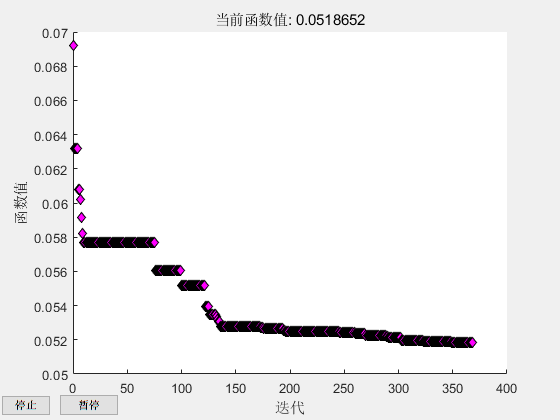

 
优化已终止:
 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件，
F(X) 满足使用 1.000000e-04 的 OPTIONS.TolFun 的收敛条件



switch workingMode
    case 1
        f = @(t)calculateTargetFunction(transMatA, kPointsMesh, t, hoppingMatrix, exportData.fermiLevel, targetHkin);
    case 2
        f = @(t)calculateTargetFunction(transMatA, kPointsMesh, t, hoppingMatrix, fermiLevel, targetHkin);
end
fminuncOptions = optimoptions('fminunc', "Algorithm","quasi-Newton", "MaxIterations", 1000,...
    "PlotFcn","optimplotfval", "Display","iter",'FunctionTolerance',1e-9,...
    "MaxFunctionEvaluations", 4000);
fminsearchOptions = optimset('Display', 'iter', 'FunValCheck', 'on', 'PlotFcns', @optimplotfval);
% [x,fval,exitflag,output,grad,hessian] = fminunc(f, initialHoppingParameter, fminuncOptions);
[x,fval,exitflag,output] = fminsearch(f, initialHoppingParameter, fminsearchOptions);


% Visualize the calulate result, uncomment if you need
updatedHoppingParameter = num2cell(x);

未定义函数或变量 'x'。

calcHkin = zeros(1, length(kPointsMesh));
initHkin = zeros(1, length(kPointsMesh));
for loopIndex = 1:length(kPointsMesh)
    calcHkin(loopIndex) = calculateKineticHamiltonian(transMatA, kPointsMesh(1:3, loopIndex)', updatedHoppingParameter, hoppingMatrix);
    initHkin(loopIndex) = calculateKineticHamiltonian(transMatA, kPointsMesh(1:3, loopIndex)', hoppingParameter, hoppingMatrix);
end
diff = calculateDifference(1, kPointsMesh(4, :)', fermiLevel ,calcHkin, targetHkin);
switch workingMode    
    case 1
        figure();
        scatter3(kPointsMesh(1, :), kPointsMesh(2, :), real(calcHkin) - exportData.fermiLevel, 1);
        figure();
        scatter3(kPointsMesh(1, :), kPointsMesh(2, :), real(diff), 1);
    case 2
        figure();
        plot(kPointsMesh(4, :), real(calcHkin) - fermiLevel, 'b');
        hold on;
        plot(kPointsMesh(4, :), real(targetHkin), 'r');
        plot(kPointsMesh(4, :), real(initHkin) - fermiLevel, 'k--');
        legend(["Calculate", "Target", "Initial"]);
        hold off;
end

## External Function

function Hkin = calculateKineticHamiltonian(transMat, kpointsRecip, hoppingParameter, hoppingMatrixProcessed)
Hkin = 0;
for hoppingOrder = 1: length(hoppingParameter)
    sum = 0;
    hoppingLength = length(hoppingMatrixProcessed{hoppingOrder}(:, 1));
    a1part = cell(1, hoppingLength);
    a2part = cell(1, hoppingLength);
    a3part = cell(1, hoppingLength);
    dotpart = zeros(1, hoppingLength);
    for numIdx = 1: hoppingLength
        a1part{numIdx} = hoppingMatrixProcessed{hoppingOrder}(numIdx, 1).*transMat(1, :);
        a2part{numIdx} = hoppingMatrixProcessed{hoppingOrder}(numIdx, 2).*transMat(2, :);
        a3part{numIdx} = hoppingMatrixProcessed{hoppingOrder}(numIdx, 3).*transMat(3, :);
        dotpart(numIdx) = dot(kpointsRecip, a1part{numIdx} + a2part{numIdx} + a3part{numIdx});
        sum = sum + exp(1i*dotpart(numIdx));
    end
    Hkin = Hkin + hoppingParameter{hoppingOrder}*sum;
end
end

% This calculateDifference function can be customized depending on your
% fitting error method.
function diff = calculateDifference(workingMode, kpointsRecip, fermiLevel ,calcHkin, targetHkin)
difference = zeros(1, length(kpointsRecip));
for loopIndex = 1: length(kpointsRecip)
    difference(loopIndex) = calcHkin(loopIndex) - fermiLevel - targetHkin(loopIndex);
end

switch workingMode
    case 1
        diff = real(difference);
    case 2
        [~, maxIdx] = max(abs(difference));
        diff = real(difference(maxIdx));
    case 3
        diff = mean(real(difference));
    case 4
        diff = var(real(difference));
end
end

function fittingDifference = calculateTargetFunction(transMatA, kPointsMesh, hoppingParameter, hoppingMatrix, fermiLevel, targetHkin)
hoppingParameterCell = num2cell(hoppingParameter);
Hkin = zeros(1, length(kPointsMesh));
for loopIndex = 1:length(kPointsMesh)
    Hkin(loopIndex) = calculateKineticHamiltonian(transMatA, kPointsMesh(1:3, loopIndex)', hoppingParameterCell, hoppingMatrix);
end
diff = calculateDifference(2, kPointsMesh(4, :)', fermiLevel, Hkin, targetHkin);
fittingDifference = abs(diff);
end